## Questions from the paper.

**(a). **Estimating based on the second oscillation on 2A, the period is ~21 hours at 35 deg-celsius, just under 22 hours at 30-deg celsius, and ~23 hours at 35 deg-celsius. The period on 1C is also around 22 hours.

**(b) **Mutant bacteria that have circadian periods very different than 24 hours might find it hard to "relate" with the 24-hour day-night cycle of earth. Consequently, depending on the exact time period, they will experience a different sense of time with respect to that of the earth's and other species. This puts them at a competitive disadvantage, since they will find it harder to adapt to the environment and find it difficult to regulate periodic processes on an everyday basis. This different perception of time could make them weaker to predators.

## KaiC Model

Autophosphorylation model:


$${\frac{dK_p}{dt}} = \left({b \frac{K_P^n}{K_M^n+K_P^n}} + 0.1\right)\left(K_{tot}-K_P\right) - P_P.K_P$$


Dephosphorylation model:


$${\frac{dP_p}{dt}} = k\left({ a\frac{K_P^6}{K_M^6+K_P^6}} - P_P\right)$$


#### Parameters

% For autophosphorylation.
Ktot = 3;                   %Total kinase (phosph. and unphosph.)
K_P = [0:Ktot/100:Ktot];    %Phosphorylated (active) kinase
K_M = 1;                    %K_M for activating of the kinase & phosphatase
b = 0.8;                    %scaling in dK_P/dt
n = 6;                      %cooperativity

% For dephosphorylation.
a = 2;                      %scaling in dP_P/dt

#### Nullclines

Parts **(c)** and **(d)**.

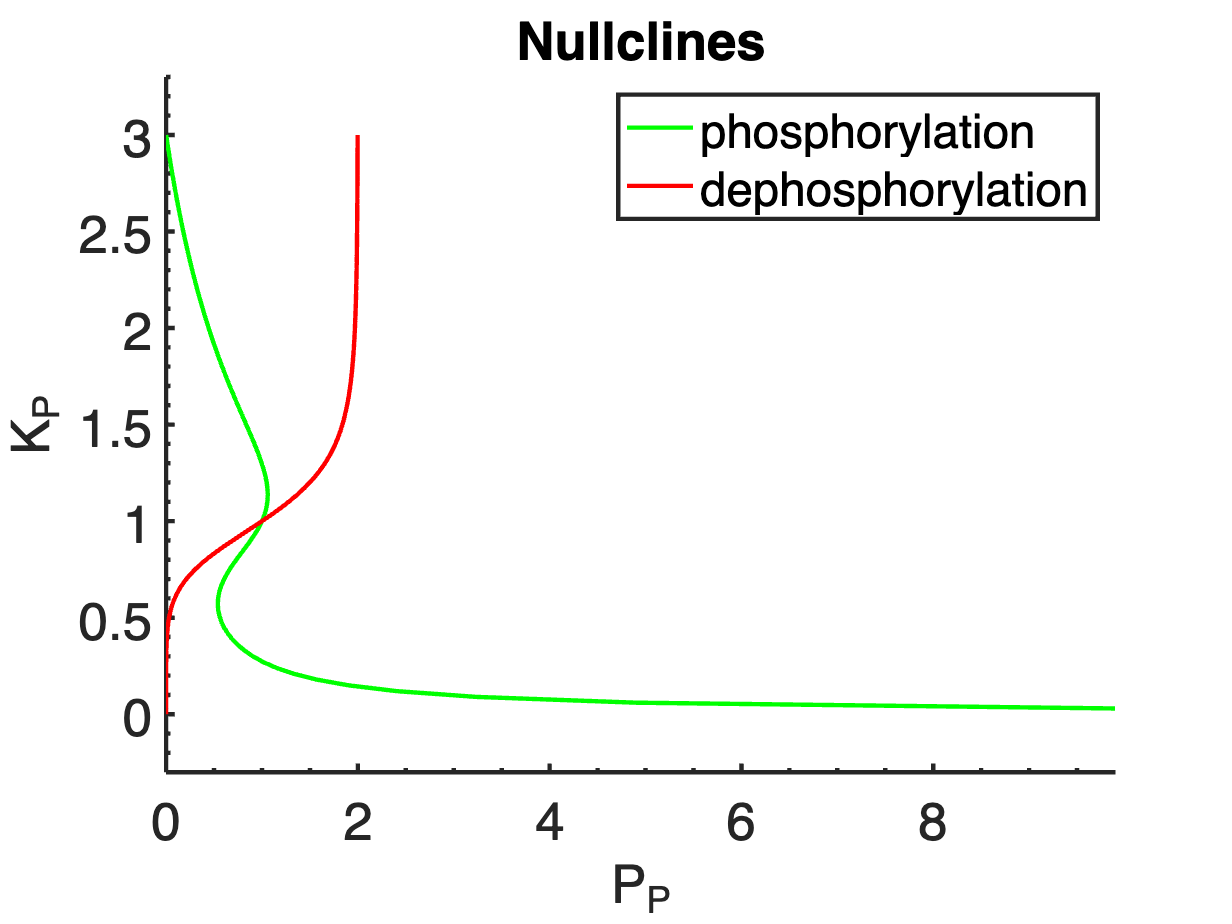

% the dKP nullcline (Psolve):
Psolve_phospho = (b.*K_P.^n./(K_M^n + K_P.^n)+0.1).*(Ktot -K_P)./K_P;

% the dKP nullcline (Psolve):
Psolve_dephospho = a.*K_P.^n./(K_M^n + K_P.^n);

figure; hold on; zoom on;
% plot nullcline.
plot(Psolve_phospho, K_P, 'g-');
plot(Psolve_dephospho, K_P, 'r-');
% set plot parameters.
title('Nullclines');
xlabel('P_P');
ylabel('K_P');
legend('phosphorylation', 'dephosphorylation');
PrettyFig;

**(e).** The fixed point occurs at the intersection of the nullclines, at $(P_P = 1, K_P = 1)$.

**(f).** The fixed point is **unstable**.

**(g). **The Jacobian is: 

    
$$\pmatrix{
-\frac{(10P_P+9)K_P^{12} + (20P_P+58)K_P^6-144K_P^5+10P_P+1}{10(K_P^6 + 1)^2} &
-K_P & \cr
\frac{12kK_P^5}{(K_P^6 + 1)^2} &
-k
}$$


    Evaluated at the fixed point, (1, 1), we obtain:

    
$$\pmatrix{
0.9 &
-1 & \cr
3k &
-k
}$$


    The eigenvalues are then:

    
$$\lambda_1 = \frac{1}{20}\left(9 - 10k - \sqrt{100k^2 - 1020k + 81}\right)$$


    
$$\lambda_2 = \frac{1}{20} \left(9 - 10k + \sqrt{100k^2 - 1020k + 81}\right)$$


    If $k<<1$,

        
$$\lambda_1 = \frac{1}{20} \left(-10k\right)$$


        
$$\lambda_2 = \frac{1}{20} \left(18 -10k\right)$$


The first eigenvalue is always *negative*, while the second eigenvalue is always *positive*. This validates that the fixed point is unstable as analyzed earlier. Specifically, the fixed point is a saddle point. It converges to a point on the K_P axis (fast time scale) and diverges on the P_P axis (slow time scale).�

#### Verifying that the equations oscillate

Part **(h)**.

The oscillations are plotted for **k = 0.0009**. At this value, the period of the oscillation is **T = ~1440** (see first complete red curve from T = *~1250 to ~2690*, for instance).

Further, the plots verify that equations (1) and (2) do in fact oscillate.

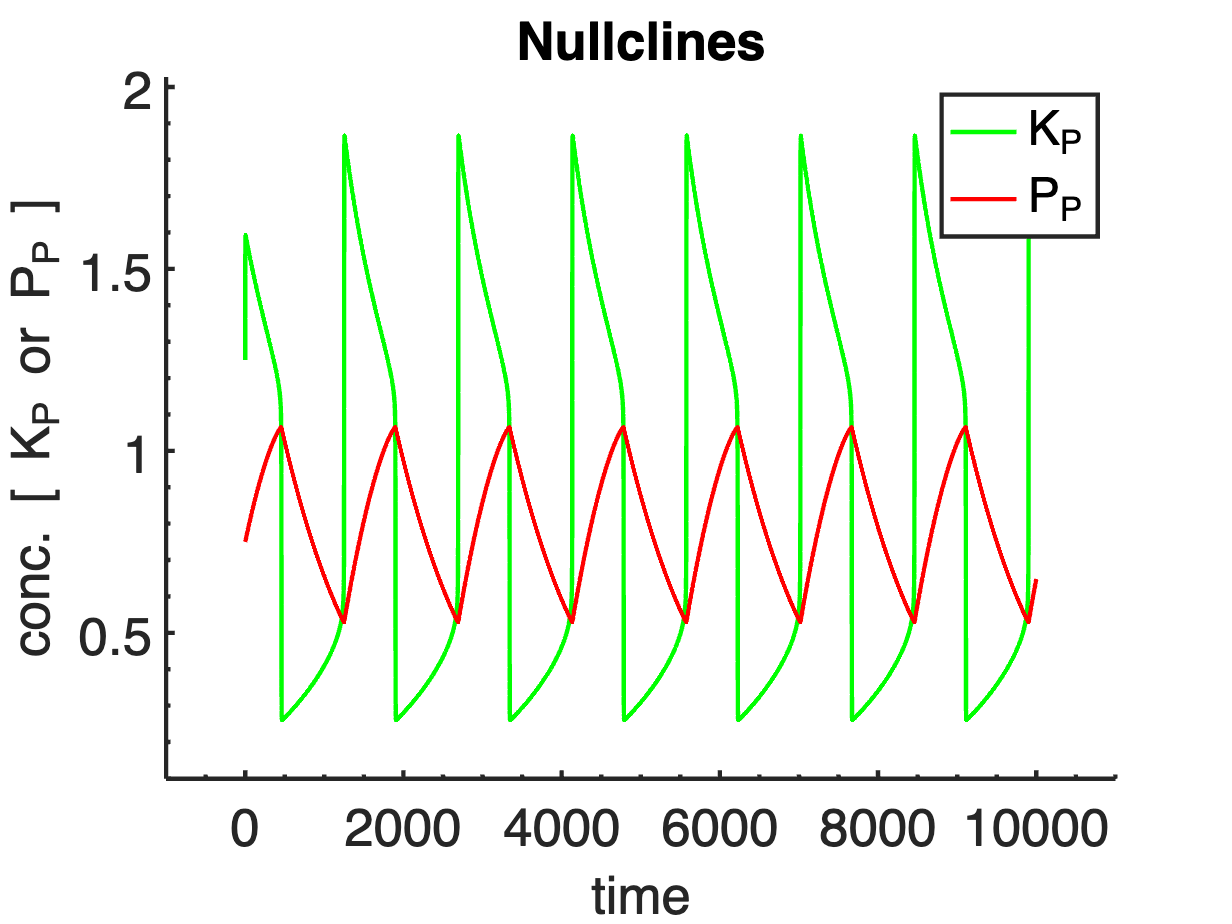

k = 0.0009;
% plot for k = 0.001;
dydt = @(t,y)[
    (Ktot-y(1)).*(b.*y(1).^n./(K_M^n + y(1).^n)+0.1)-y(2).*y(1); ...
    k*(a.*y(1).^n./(K_M^n + y(1).^n)-y(2))
];
% numerical integration.
[T,Y] = ode45(dydt,[0,10000],[1.25 0.75]);

figure; hold on; zoom on;
plot(T, Y(:, 1), 'g-');
plot(T, Y(:, 2), 'r-');
% set plot parameters.
title('Nullclines');
xlabel('time');
ylabel('conc. [ K_P or P_P ]');
legend('K_P', 'P_P');
PrettyFig;

#### Phase-plane plot

Part **(i)**.

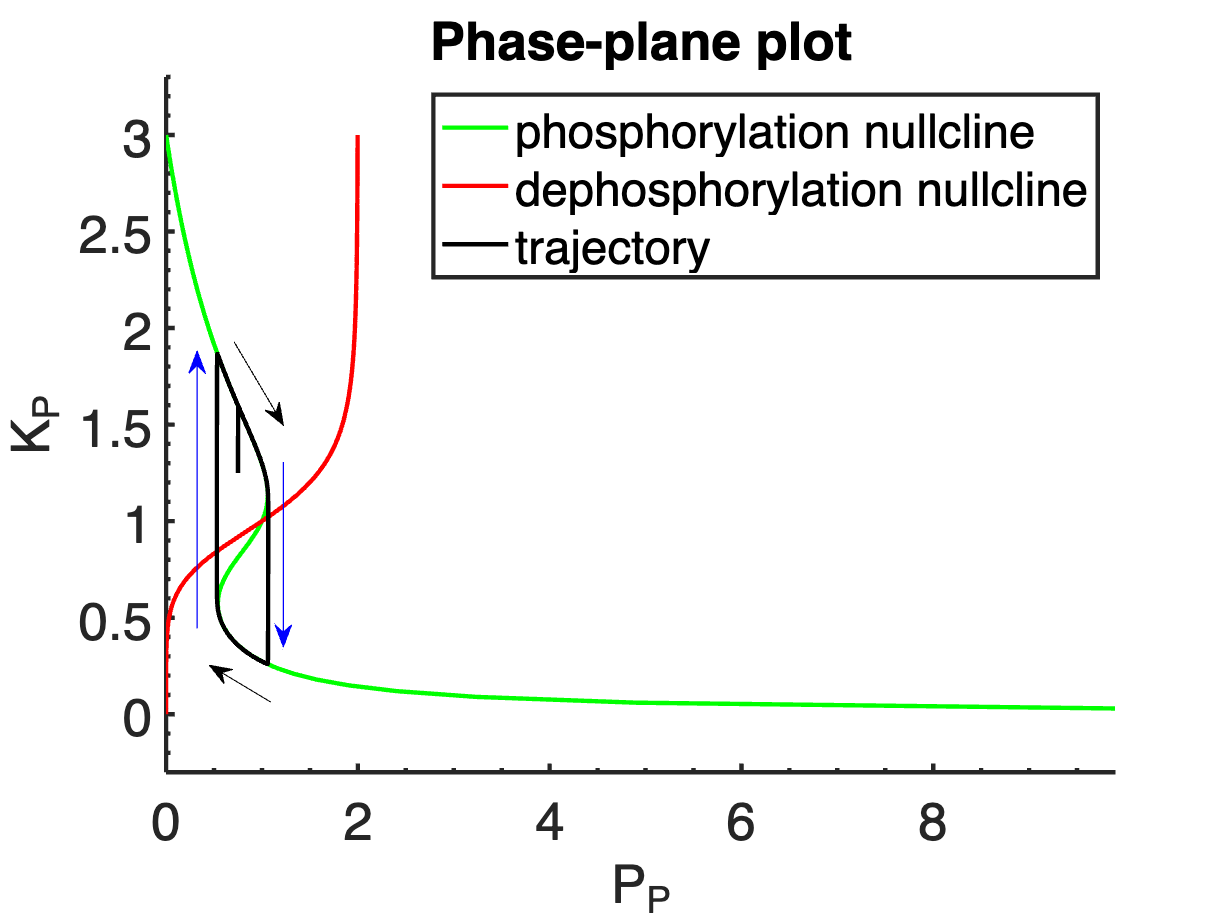

figure; hold on; zoom on;
% plot nullcline.
plot(Psolve_phospho, K_P, 'g-');
plot(Psolve_dephospho, K_P, 'r-');
plot(Y(:, 2), Y(:, 1), 'k-');
% draw arrows for trajectory.
annotation('textarrow', [.19 .23],[.63 .54]);
annotation('textarrow', [.22 .17],[.24 .28]);
annotation('textarrow', [.23 .23],[.50 .30], 'Color', 'blue');
annotation('textarrow', [.16 .16],[.32 .62], 'Color', 'blue');
% set plot parameters.
title('Phase-plane plot');
xlabel('P_P');
ylabel('K_P');
legend('phosphorylation nullcline', 'dephosphorylation nullcline', 'trajectory');
PrettyFig;

**(j).** The arrows show the direction of the trajectory. States of the system exist on black arrows, while the blue arrows indicate a transition of the system with no (or very few) points lying on them. Snapshots of the trajectory over time is shown below.

#### Oscillation trajectory over time -- GIF.

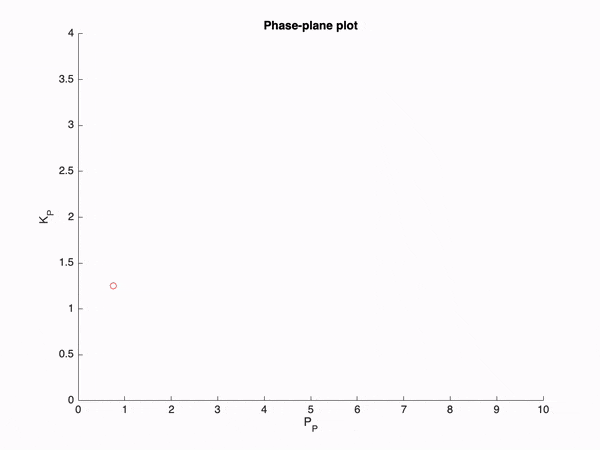

**(k).** The trajctory solution is hugging the phosphorylation nullcline, and jumps across the fixed point from its lower to higher K_P value ranges.

**(l). **Since the system converges toward a saddle along the K_P axis and diverges along the P_P axis, the system tends to jump across when it approaches the fixed point on the P_P axis from either side of the said fixed point.

#### Vector field

Part **(m)**.

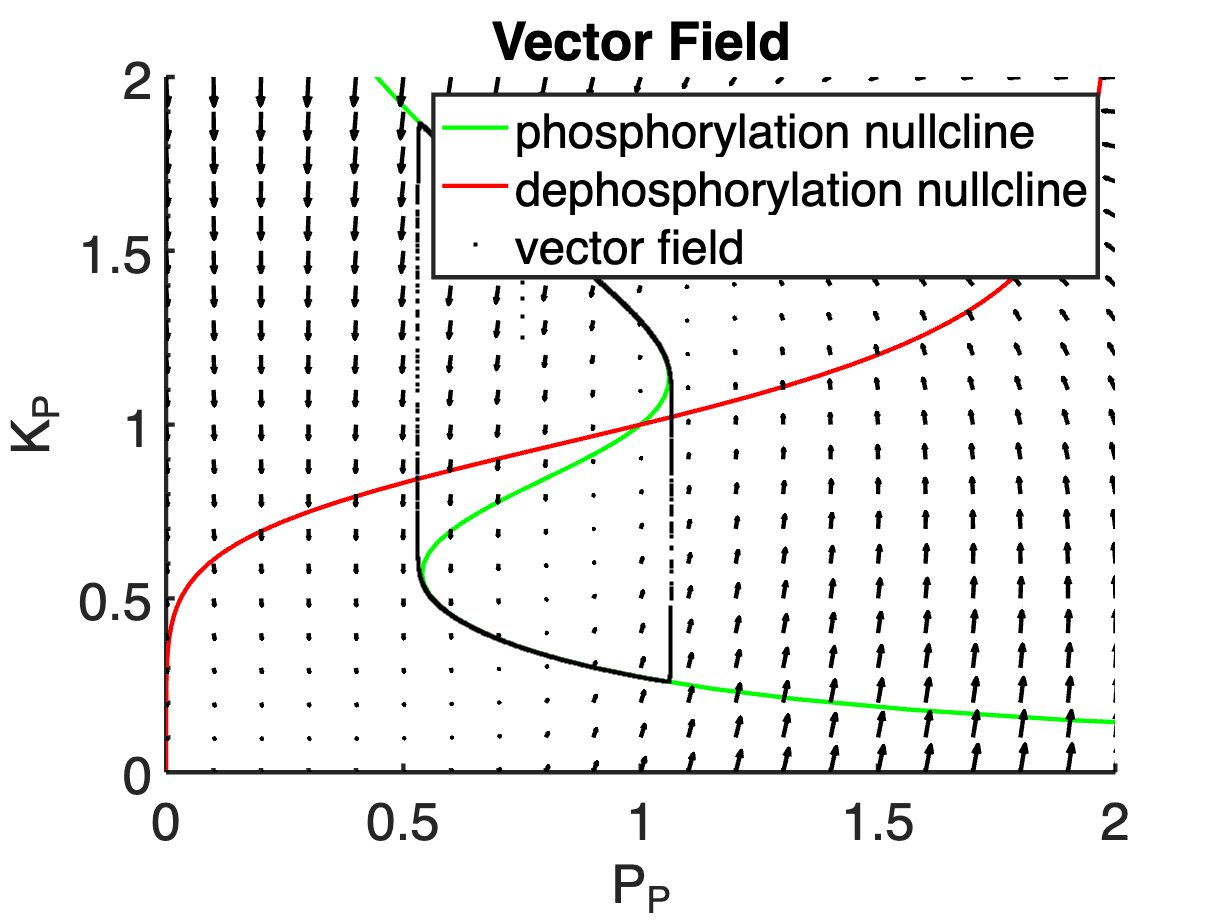

figure; hold on; zoom on;
% plot nullcline.
plot(Psolve_phospho, K_P, 'g-');
plot(Psolve_dephospho, K_P, 'r-');
plot(Y(:, 2), Y(:, 1), 'k.');
[y1, y2] = meshgrid([0:.1:3],[0:.1:3]);
dy1dt = (Ktot-y1).*(b.*y1.^n./(K_M^n + y1.^n)+0.1)-y2.*y1;
dy2dt = k*(a.*y1.^n./(K_M^n + y1.^n)-y2);
% reascale P_P component.
dy2dt = dy2dt * 5000;
quiver(y1, y2, dy1dt, dy2dt, 'color', 'k');
% set plot parameters.
title('Vector Field');
xlabel('P_P');
ylabel('K_P');
legend('phosphorylation nullcline', 'dephosphorylation nullcline', 'vector field');
axis([0 2 0 2]);
PrettyFig;

**(n). **KaiA is known to promote autophosphorylation of KaiC, whereas KaiB attenuates the effect of KaiA (based on Nakajima et al.); further, KaiA also inhibits dephosphorylation. Their effects could perhaps be analyzed by observing the system at contrasting levels of KaiA and KaiB; If KaiA values are much higher than KaiB, the rate of autophosphorylation will be very high and KaiC will tend to stay phophorylated. On the other hand, if KaiB levels are much higher than KaiA levels, the effect of KaiA would likely be completely masked - both for phosphorylation and dephophorylation, effectively simplifying to the model simulated in this problem set. 

Part **(o)**.

(3-x)((0.8 x^6)/(1^6 + x^6)+0.1) - y(x)

Based on the Poincare-Bendixson theorem, *if R is a finite region in the plane lying between two simple closed curves D1 and D2, and Fis the velocity vector field for the system (1). If at each point of D1 and D2, the field Fpoints toward the interior of R, then the system has a closed trajectory lying inside R. *

Consider the vector fields of the system (the first from above, and the second from WolframAlpha using streamplots for better clarity).

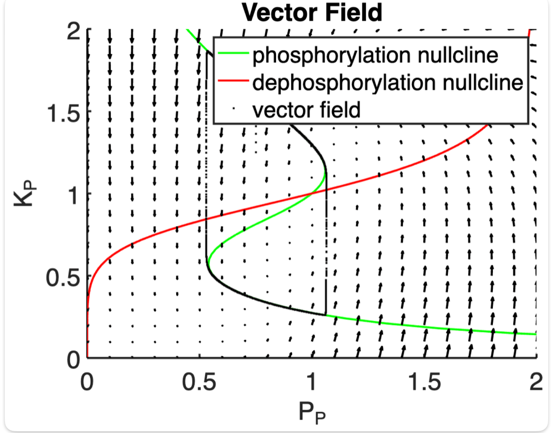  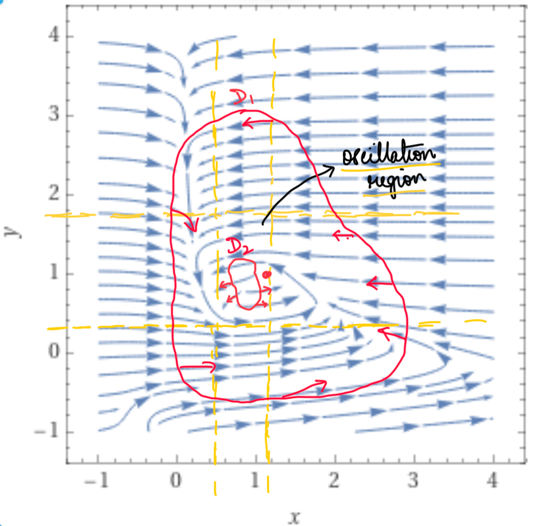

From the vector field above, two such curves, D1 and D2 can be identified that define a region R within which the oscillation trajectory lies. All the vectors on D1 point inward into R, while all those on D2 point outward into R. Hence, according to the theorem, the system has a limit cycle for the given parameters.